% Setup:
cd('C:\Users\user\Dropbox\projekte\Lehrveranstaltungen\MA\Simulations\matlab\flexible_arm')
addpath functions

AIM: Automatic numerical solving procedure of Euler-Bernoulli beam PDE (4th order) for different BC.

# 1. Problem formulation

## System sketch

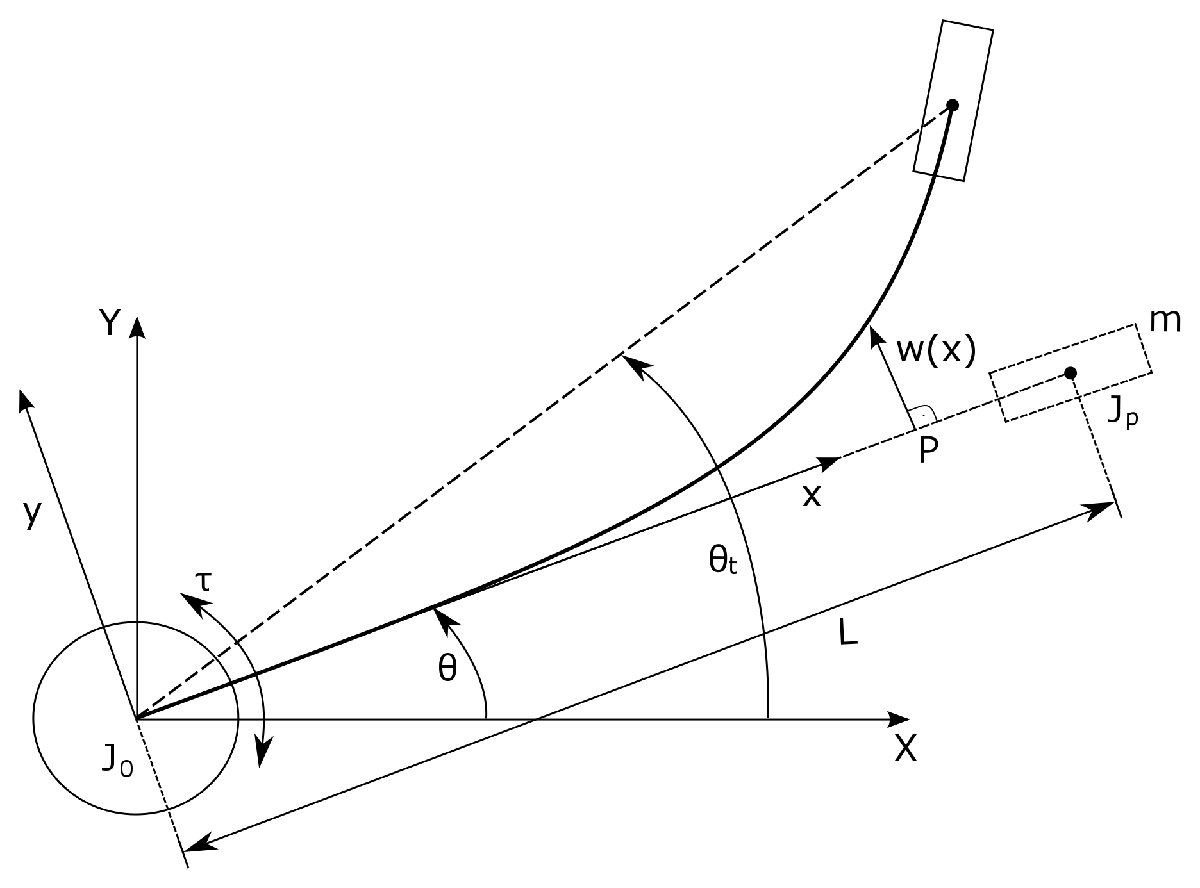

## Distributed parameter representation

Linearized dynamic equations with input $u(t):=\tau(t)$:


$$J\ddot\theta(t)+A\rho\int^L_0x\ddot w(x,t)dx+mL\,\ddot w(L,t)=u(t)\\
EI\,w''''(x,t)+A\rho \,x\ddot\theta(t)+A\rho\,\ddot w(x,t)=0$$


Alternatively: modulate 2nd equation by $x$ over $[0,L]$ and plug into 1st equation


$$\Rightarrow\quad\left(J-\frac{A\rho L^3}{3}\right)\ddot\theta(t)+mL\,\ddot w(L,t)-EI\big(L\,w'''(L,t)-w''(L,t)+w''(0,t)\big)=u(t)$$


(can be simplified by BC)

## Boundary conditions

Possible boundary condition settings:

$(I.)$:


$$w(0,t)=w'(0,t)=0\\
w''(L,t)=0\\
EI\,w'''(L,t)=m\big(L\ddot\theta(t)+\ddot w(L,t)\big)$$


$(II.)$:


$$w(0,t)=0\\
EI\,w''(0,t)=J_0\big(\ddot\theta(t)+\ddot w'(0,t)\big)-u(t)\qquad\text{(balance of moments at base)}\\
EI\,w''(L,t)=-J_P\big(\ddot\theta(t)+\ddot w'(L,t)\big)\,\,\,\qquad\qquad\text{(balance of moments at tip)}\\
EI\,w'''(L,t)=m_p\big(L\ddot\theta(t)+\ddot w(L,t)\big)\,\,\,\,\,\,\quad\qquad\text{(balance of shear forces at tip)}$$


$(III.)$:


$$w(0,t)=w'(0,t)=0\\
w''(L,t)=w'''(L,t)=0$$


## Parameters

Physical parameters: (firstly normalized)

% Arm-payload:
E = 1.96e11;     % [N/m^2]
I = 2.08e-12;    % [m^4]
Al = 25e-6;      % [m^2]
L = 0.25;        % [m]
rho = 10.667e3;  % [kg/m^3]
m = 0.2;         % [kg]
J0 = 1e-3;       % [kg*m^2]
Jp = 1e-3;       % [kg*m^2]
% E = 1; I = 1;
% Al = 1; L = 1;
% rho = 1; m = 1;
% J0 = 1; Jp = 1;
J = J0+Al*rho*L^3/3+Jp+m*L^2;

Simulation specifications:

N = 9;              % approbetamation order
h = 1e-4;           % spatial step size
X = 0:h:L;          % spatial domain
time = 0:1e-2:15;   % time scale
epsilon = 1e-1;     % numeric accuracy

# 2. Constrained mode method

Ansatz: $\ddot\theta(t)=0\,\forall t\geq0$ (for $u(t)=0$)

Resulting system form:


$$w''''(x,t)+\frac{A\rho}{EI}\,\,\ddot w(x,t)=0$$


Seperation of variables (SoV):


$$w(x,t)=:\phi(x)q(t)\quad\Rightarrow\quad\frac{EI}{A\rho}\,\frac{\phi''''(x)}{\phi(x)}=-\frac{\ddot q(t)}{q(t)}\quad\overset{!}{=}\quad\omega^2$$


Dynamic equations:


$$\ddot q(t)+\omega^2q(t)=0\\
\phi''''(x)-\frac{A\rho}{EI}\,\omega^2\,\phi(x)=0$$


# 2.1 Eigenfunctions

The respective boundary value problem (BVP) has the solution form:


$$\phi(x)=A\sin(\beta x)+B\cos(\beta x)+C\sinh(\beta x)+D\cosh(\beta x)\\
\qquad=A\sin(\beta x)+B\cos(\beta x)+\left(\frac{C}{2}+\frac{D}{2}\right)\,e^{\beta x}+\left(-\frac{C}{2}+\frac{D}{2}\right)\,e^{-\beta x}$$


with eigenvalue $\beta^4:=\frac{A\rho}{EI}\,\omega^2$. Plugging this into the BC leads to the characteristic matrix.

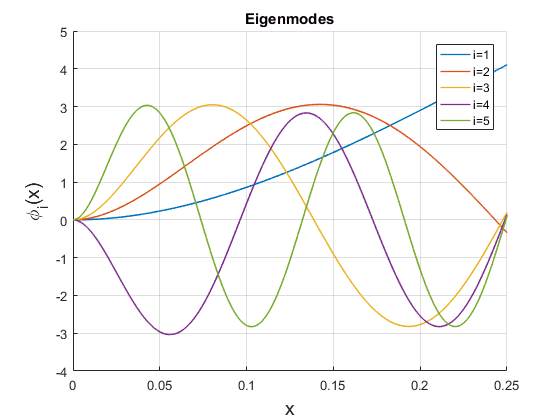

% Characteristic matrix: (use function 'charMat' with BC as array)
syms beta real
M1 = charMat([1 0 0 0;0 1 0 0;0 0 1 0;m/(E*I)*beta^4 0 0 1],[0;0;L;L],beta);
M2 = charMat([1 0 0 0;0 J0/(E*I)*beta^4 1 0;0 -Jp/(E*I)*beta^4 1 0; ...
    m/(E*I)*beta^4 0 0 1],[0;0;L;L],beta);
M3 = charMat([1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1],[0;0;L;L],beta) ;
M = M1;
% Transcendental equation roots:
char = matlabFunction(det(M));
bsmp = 1:1:200; % samples
bsol = 0; % storage
for i=1:length(bsmp)
    tmp = fzero(char,bsmp(i));
    if (tmp>bsol(end)+epsilon)
        bsol = [bsol tmp];      
    end
end
% Eigenfunction construction:
Mf = matlabFunction(M); % A(beta)
phiarr = zeros(N,length(X));
cnr = zeros(1,N);
for i=1:N
    be = bsol(i+1); % exclude trivial solution beta=0
    P = null(Mf(be));
    if (size(P,2)==1)
        tmpfcn = @(x)(P(1)*sin(be*x)+P(2)*cos(be*x)+P(3)*sinh(be*x)+P(4)*cosh(be*x));
        tmpnorm = sqrt(integral(@(x)(tmpfcn(x).^2),0,L));
        phiarr(i,:) = tmpfcn(X)/tmpnorm; % normalized (for p=1)
    else        
        disp(strcat('Ill conditioned characteristic matrix (rank<3) at beta=',...
        num2str(be),', i=',num2str(i+1),'.'))
    end
    cnr(i) = cond(Mf(be));
end
figure; hold on
for i=1:5
    plot(X,phiarr(i,:),'LineWidth',1)
end
legend('i=1','i=2','i=3','i=4','i=5')
grid; xlabel('x','FontSize',14); ylabel('\phi_i(x)','FontSize',14);
title('Eigenmodes'); hold off

Thus the solution is represented as an infinite sum:


$$w(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)$$


with respective to the characteristic eigenvalues $\beta_i$.

# 2.2 Finite dimensional ODE

Plugging the new deformation function form into the 1st dynamic equation:


$$J\ddot\theta(t)+A\rho\overset{\infty}{\underset{i=1}{\sum}}\int^L_0x\phi_i(x)dx\,\ddot q_i(t)+mL\,\overset{\infty}{\underset{i=1}{\sum}}\phi_i(L)\ddot q_i(t)=u(t)$$



$$\Rightarrow\quad J\ddot\theta(t)-\overset{\infty}{\underset{i=1}{\sum}}\omega_i^2\left(A\rho\int^L_0x\phi_i(x)dx+mL\,\phi_i(L)\right)\,q_i(t)=u(t)$$


For the alternative version of equation 1 consider:


$$\quad\left(J-\frac{A\rho L^3}{3}\right)\ddot\theta(t)+mL\,\overset{\infty}{\underset{i=1}{\sum}}\phi_i(L)\ddot q_i(t)-EI\overset{\infty}{\underset{i=1}{\sum}}\big(L\,\phi_i'''(L)-\phi_i''(L)+\phi_i''(0)\big)q_i(t)=u(t)$$



$$\Rightarrow\quad\quad\left(J-\frac{A\rho L^3}{3}\right)\ddot\theta(t)-\overset{\infty}{\underset{i=1}{\sum}}\Big(mL\,\omega_i^2\phi_i(L)+EI\big(L\,\phi_i'''(L)-\phi_i''(L)+\phi_i''(0)\big)\Big)q_i(t)=u(t)$$


Modulating the 2nd dynamic equation with $\phi_j\,\forall j\in\{1,2,\ldots\}$ over $[0,L]$ (use orthonormality) leads to:


$$
\overset{\infty}{\underset{i=1}{\sum}}\phi_i''''(x)q_i(t)+A\rho \,x\ddot\theta(t)+A\rho\,\overset{\infty}{\underset{i=1}{\sum}}\phi_i(x)\ddot q_i(t)=0$$



$$\Rightarrow\quad
\frac{A\rho}{EI}\,\omega_j^2\,q_j(t)+A\rho \,\int_0^Lx\phi_j(x)dx\,\ddot\theta(t)+A\rho\,\ddot q_j(t)=0$$


Substituting the coefficients, the infinite dimensional ODE describing the dynamics has the form:


$$\ddot\theta(t)-\overset{\infty}{\underset{i=1}{\sum}}a_i q_i(t)=b\,u(t)\\
\ddot q_j(t)+c_jq_j(t)+d_j\ddot\theta(t)=0$$


 Simulation is performed for finite approximation of order $N$with respective state:


$$z=[\theta\,,\,\dot\theta\,,\,q_1\,,\,\dot q_1\,,\,\ldots\,,\,q_N\,,\,\dot q_N]^T$$


where the system dynamics in LTI matrix form are:


$$A =\pmatrix{0&1&0&0&\cdots&0&0 \cr 
0&0&a_1&0&\cdots&a_N&0 \cr
0&0&0&1&\cdots&0&0 \cr
0&0&-(c_1+d_1a_1)&0&\cdots&-d_1a_N \cr
\vdots&\vdots&\vdots&\vdots&\ddots&\vdots&\vdots \cr
0&0&0&0&\cdots&0&1 \cr
0&0&-d_Na_1&0&\cdots&-(c_N+d_Na_N)&0} 
\,,\quad
B =\pmatrix{0 \cr b \cr 0 \cr -d_1b \cr \vdots \cr 0 \cr -d_Nb}$$


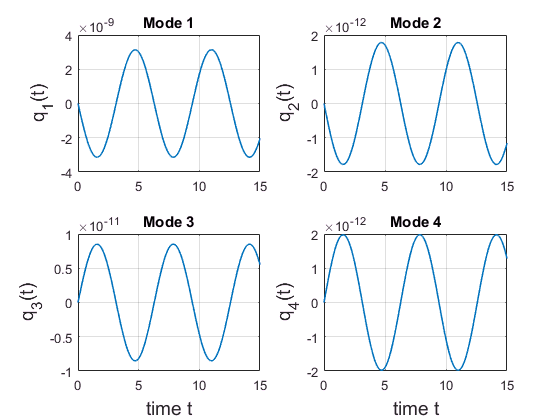

% System dynamics:
omeg = sqrt(E*I/Al*rho)*bsol(2:N+1).^2;
% D2phi = (diff(psiarr',2)/h^2)';
% D3phi = (diff(psiarr',3)/h^3)';
aarr = (omeg.^2.*(Al*rho*trapz(X.*phiarr,2)'+m*L*phiarr(:,end)'))/J;
b = 1/J;
% aarr = (m*L*omeg.^2.*phiarr(:,end)'+E*I*(L*D3phi(:,end)'-D2phi(:,end)'+D2phi(:,1)'))/(J-Al*rho*L^3/3);
% b = 1/(J-Al*rho*L^3/3);
carr = omeg.^2/(E*I);
darr = trapz(X.*phiarr,2)';
A = [0 1 zeros(1,2*N);                               % Dtheta
    0 0 kron(aarr,[1 0])];                           % D2theta
for i=1:N
    tmprow = [0 0 zeros(1,2*i-1) 1 zeros(1,2*(N-i))  % Dr_i
        0 0 -kron(darr.*aarr,[1 0])];                % D2r_i
    tmprow(2,1+2*i) = tmprow(2,1+2*i) - carr(i);     % D2r_i (direct state influence)
    A = [A;tmprow];
end
B = [0;b;-kron(b*darr',[0;1])];
% Time simulation:
z0 = zeros(2*(N+1),1);
u = @(t)(5e-2*sin(t));%(torque1(t))
% u = @(t)(torque1(t));
fdyn = @(t,z)(A*z+B*u(t));
[time,zsol] = ode15s(fdyn,time,z0); % stiff solver
% Test vibration components:
figure;
subplot(2,2,1); plot(time,zsol(:,1+2*1),'LineWidth',1)
grid; ylabel('q_1(t)','FontSize',14); title('Mode 1')
subplot(2,2,2); plot(time,zsol(:,1+2*2),'LineWidth',1)
grid; ylabel('q_2(t)','FontSize',14); title('Mode 2')
subplot(2,2,3); plot(time,zsol(:,1+2*3),'LineWidth',1)
grid; xlabel('time t','FontSize',14); ylabel('q_3(t)','FontSize',14); title('Mode 3')
subplot(2,2,4); plot(time,zsol(:,1+2*4),'LineWidth',1)
grid; xlabel('time t','FontSize',14); ylabel('q_4(t)','FontSize',14); title('Mode 4')

# 2.3 Compound system simulation

Overall deformation:


$$w(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)\approx\overset{N}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)$$


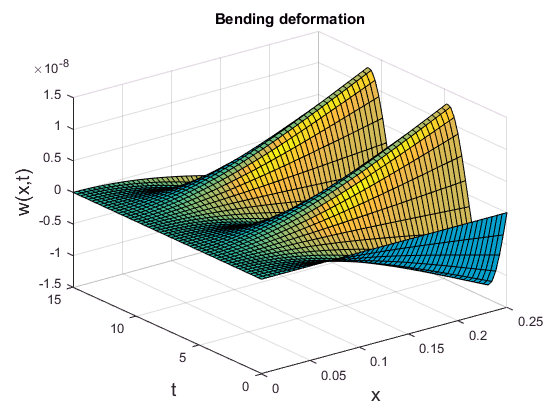

% Deformation solution:
qsol = zsol(:,3:2:end-1)';
time = time';
w = zeros(length(time),length(X));
for j=1:length(time) % build over time
    tmpcol = sum(diag(qsol(:,j))*phiarr);
    w(j,:) = tmpcol;
end
% Select rough grid:
nappr = 50; % grid approximation
lx = length(X); indx = 1:round((lx-1)/nappr):lx;
Xpl = X(indx);
lt = length(time); indt = 1:round((lt-1)/nappr):lt;
Tpl = time(indt)';
% 3D deformation plot:
wpl = w(indt,indx);
figure; surfl(Xpl,Tpl,wpl); %shading flat
xlabel('x','FontSize',14); ylabel('t','FontSize',14); zlabel('w(x,t)','FontSize',14);
title('Bending deformation')

Total flexible arm movement (see figure):


$$(X,Y)=\big[x\cos(\theta(t))-w(x,t)\sin(\theta(t))\,,\,x\sin(\theta(t))+w(x,t)\cos(\theta(t))\big]$$


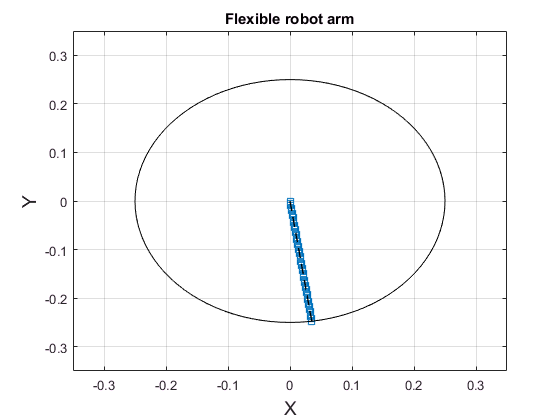

% Cartesian representation:
thetasol = zsol(:,1)'; % rotational transformation (over time)
Xcart = zeros(length(time),length(X)); Ycart = zeros(length(time),length(X));
Xnom = zeros(length(time),length(X)); Ynom = zeros(length(time),length(X));
for j=1:length(time) % build over time    
    Xcart(j,:) = X*cos(thetasol(j)) - w(j,:)*sin(thetasol(j));
    Ycart(j,:) = X*sin(thetasol(j)) + w(j,:)*cos(thetasol(j));
    Xnom(j,:) = X*cos(thetasol(j));
    Ynom(j,:) = X*sin(thetasol(j));
end
% Flexible arm plot:
for k=1:length(Tpl)
    plot(Xcart(indt(k),indx),Ycart(indt(k),indx),'--s'); grid
    hold on; plot(Xnom(indt(k),indx),Ynom(indt(k),indx),'--black','LineWidth',1);
    circle(0,0,L); hold off
    axis([-L L -L L]+[-0.1 0.1 -0.1 0.1])
    xlabel('X','FontSize',14); ylabel('Y','FontSize',14); title('Flexible robot arm')
    MV(k) = getframe; % movie structure: [figure; movie(MV)]
end

COMMENTS:

- relatively simple precalculations due to assumption: no direct effect of deformation on rotation angle (high hub intertia)

- obtained model has lots of couplings wrt. mode states

- difficult time simulation for high order (very stiff system)

- every mode contains more frequencies than its eigenfrequency and the excitation part

- results are too high scaled (amplitude) and seem unreasonable

- hard to validate due to comlicated structure and different coefficients than in the literature

# 3. Unconstrained mode method

Ansatz: $u(t)=0$

Choice of variables:


$$\theta(t)=\eta(t)+\gamma\,q(t)\\
w(x,t)=\phi(x)q(t)$$


where the parameter $\gamma$ such that:


$$J\gamma+A\rho\int^L_0x\phi(x)dx+mL\,\phi(L)=0$$


Plugging this into the original dynamic equations:


$$J\ddot\eta(t)+\Big[J\gamma+A\rho\int^L_0x\phi(x)dx+mL\,\phi(L)\Big]\,\ddot q(t)=u(t)$$


and finally:


$$J\ddot\eta(t)=0\\
EI\,\phi''''(x)q(t)+A\rho\,\big(x\ddot\eta(t)+(\gamma x+\phi(x))\,\ddot q(x,t)\big)=0$$


Seperation of variables:


$$\Rightarrow\quad\frac{EI}{A\rho}\,\frac{\phi''''(x)}{\gamma x+\phi(x)}=-\frac{\ddot q(t)}{q(t)}\quad\overset{!}{=}\quad\omega^2$$


Introducing the new variable $\Phi(x):=\phi(x)+\gamma x$ a homogenous system is obtained:


$$\ddot q(t)+\omega^2q(t)=0\\
\Phi''''(x)-\frac{A\rho}{EI}\,\omega^2\,\Phi(x)=0$$


with adjusted boundary conditions:


$$\Phi(0)=\Phi''(L)=0\\
\Phi'(0)=\gamma\\
\Phi'''(L)=-\frac{m\omega^2}{EI}\,\Phi(L)
$$


The 3rd BC shall be reformulated independently of the auxiliary parameter $\gamma$. Therefore first the new spatial variable $\Phi$shall be related to $\gamma$ with:


$$J\gamma=-A\rho\int^L_0x\big(\Phi(x)-\gamma x\big)dx-mL\,\big(\Phi(L)-\gamma L\big)\\
\quad=-A\rho\int^L_0x\Phi(x)dx+A\rho\frac{L^3}{3}\gamma-mL\Phi(L)+mL^2\gamma$$



$$\Rightarrow\quad\left(J_0+J_P\right)\gamma=-\frac{EI}{\omega^2}\,\int_0^Lx\,\Phi''''(x)dx-mL\Phi(L)\\
\qquad\qquad\quad\,\,\,=-\frac{EI}{\omega^2}\Big(x\Phi'''(x)\,\big|_0^L-\int_0^L\Phi'''(x)dx\Big)-mL\Phi(L)\\
\qquad\qquad\quad\,\,\,=-\frac{EI}{\omega^2}\Big(L\Phi'''(L)-\Phi''(L)+\Phi''(0)\Big)-mL\Phi(L)\\
\qquad\qquad\quad\,\,\overset{BC}{=}-\frac{EI}{\omega^2}\Big(-\frac{mL\omega^2}{EI}\,\Phi(L)+\Phi''(0)\Big)-mL\Phi(L)\\
\qquad\qquad\quad\,\,\,=-\frac{EI}{\omega^2}\,\Phi''(0)$$


Thus the 3rd BC can be stated as:


$$\frac{EI}{J_0+J_P}\,\Phi''(0)+\omega^2\Phi'(0)=0$$


# 3.1 Eigenfunctions

The solution of the homogenized eigenvalue problem has the form:


$$\Phi(x)=A\sin(\beta x)+B\cos(\beta x)+C\sinh(\beta x)+D\cosh(\beta x)$$


where $\beta^4:=\frac{A\rho}{EI}\,\omega^2$. Then the transcendental equation is obtained by plugging this form into the BC:

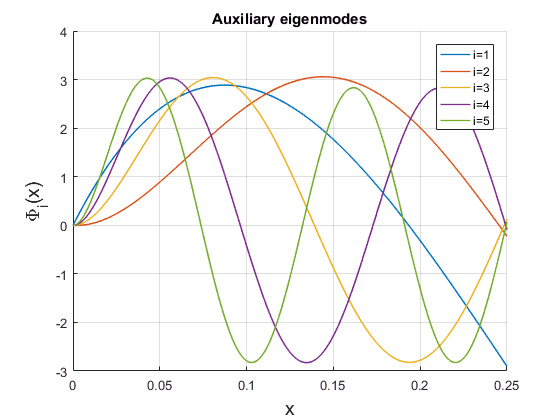

% Characteristic matrix: (use function 'charMat' with BC as array)
syms beta real
M = charMat([1 0 0 0;0 0 1 0;0 beta^4/(Al*rho) 1/(J0+Jp) 0; ...
    m/(Al*rho)*beta^4 0 0 1],[0;L;0;L],beta);
% Transcendental equation roots:
char = matlabFunction(det(M));
bsmp = 1:1:200; % samples
bsol = 0; % storage
for i=1:length(bsmp)
    tmp = fzero(char,bsmp(i));
    if (tmp>bsol(end)+epsilon)
        bsol = [bsol tmp];      
    end
end
% Auxiliary eigenfunction construction:
Mf = matlabFunction(M); % A(beta)
Phiarr = zeros(N,length(X));
cnr = zeros(1,N);
for i=1:N
    be = bsol(i+1); % exclude trivial solution beta=0
    P = null(Mf(be));
    if (size(P,2)==1)
        tmpfcn = @(x)(P(1)*sin(be*x)+P(2)*cos(be*x)+P(3)*sinh(be*x)+P(4)*cosh(be*x));
        tmpnorm = sqrt(integral(@(x)(tmpfcn(x).^2),0,L)); % auxiliary normilization
        Phiarr(i,:) = tmpfcn(X)/tmpnorm;
    else        
        disp(strcat('Ill conditioned characteristic matrix (rank<3) at beta=',...
        num2str(be),', i=',num2str(i+1),'.'))
    end
end
figure; hold on
for i=1:5
    plot(X,Phiarr(i,:),'LineWidth',1)
end
legend('i=1','i=2','i=3','i=4','i=5')
grid; xlabel('x','FontSize',14); ylabel('\Phi_i(x)','FontSize',14);
title('Auxiliary eigenmodes'); hold off

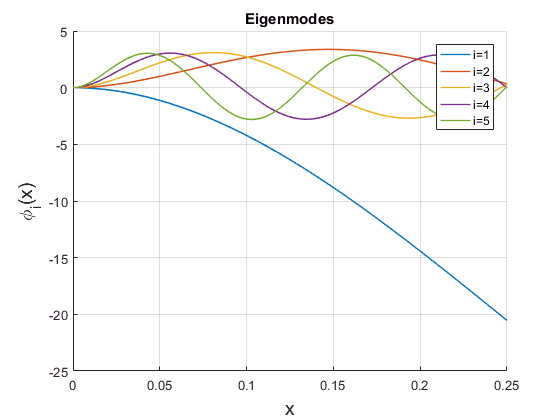

% Original eigenfunction:
omeg = sqrt(E*I/(Al*rho))*bsol(2:N+1)'.^2;
D2Phiarr = (diff(Phiarr',2)/h^2)';
gamma = -E*I/(J0+Jp).*D2Phiarr(:,1)./(omeg.^2);
phiarr = Phiarr - gamma.*X;
figure; hold on
for i=1:5
    plot(X,phiarr(i,:),'LineWidth',1)
end
legend('i=1','i=2','i=3','i=4','i=5')
grid; xlabel('x','FontSize',14); ylabel('\phi_i(x)','FontSize',14);
title('Eigenmodes'); hold off

% Check original BCs & normalization:
Dphiarr = (diff(phiarr')/h)';
D2phiarr = (diff(phiarr',2)/h^2)';
D3phiarr = (diff(phiarr',3)/h^3)';

[phiarr(:,1) Dphiarr(:,1) D2phiarr(:,end)] % BCs should equal 0 (consider related scales)

ans =    1.0e+03 *

         0   -0.0000   -0.0004
   -0.0000    0.0001   -0.0011
    0.0000    0.0002    0.0064
         0    0.0003   -0.0191
    0.0000    0.0006    0.0427
         0   -0.0009    0.0807
    0.0000   -0.0012   -0.1372
    0.0000    0.0017   -0.1908
   -0.0000    0.0021    6.1061


disp(sqrt(trapz(X,Phiarr.^2,2))) % norms should equal 1

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



COMMENT: All required conditions seem to be fulfilled in a reasonable way.

Thus the solution variables are represented by infinite sums:


$$w(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)
\,,\quad
\theta(t)=\eta(t)+\overset{\infty}{\underset{i=1}{\sum}}\,\gamma_iq_i(t)$$


with respective to the characteristic eigenvalues $\beta_i$.

# 3.2 Finite dimensional ODE

Plugging the solution forms into the original dynamic equations we get for the 1st one:


$$J\ddot\eta(t)+\overset{\infty}{\underset{i=1}{\sum}}\left[J\gamma_i+A\rho\int^L_0x\phi_i(x)dx+mL\,\phi_i(L)\right]\,\ddot q_i(t)=u(t)$$



$$\Rightarrow\quad J\ddot\eta(t)=u(t)$$


and for the 2nd dynamic equation:


$$EI\,\overset{\infty}{\underset{i=1}{\sum}}\phi_i''''(x)q_i(t)+A\rho\overset{\infty}{\underset{i=1}{\sum}}\big(\gamma_ix+\phi_i(x)\big)\,\ddot q_i(t)+A\rho\,x\ddot\eta(t)=0$$



$$\Rightarrow\quad \,\overset{\infty}{\underset{i=1}{\sum}}\omega_i^2\big(\gamma_ix+\phi_i(x)\big)q_i(t)+\overset{\infty}{\underset{i=1}{\sum}}\big(\gamma_ix+\phi_i(x)\big)\,\ddot q_i(t)=-\frac{x}{J}\,u(t)$$



$$\Leftrightarrow\quad \,\overset{\infty}{\underset{i=1}{\sum}}\Phi_i(x)\big(\ddot q_i(t)+\omega_i^2q_i(t)\big)=-\frac{x}{J}\,u(t)$$


Modulating the relation with $\Phi_j$ with respect to $x$ over $[0,L]$ and using the orthonormality of the auxiliary eigenfunction $<\Phi_i,\Phi_j>=0\,\forall i\neq j$, $<\Phi_i,\Phi_i>=1$, as well as the definition of $\gamma_j\,\forall j\in\{1,2,\ldots\}$ we obtain:


$$\ddot q_j(t)+\omega_j^2q_j(t)=-\frac1J\int_0^Lx\Phi_j(x)dx\,u(t)=\underset{=:k_j}{\underbrace{-\frac{1}{JA\rho}\left(\frac{EI}{\omega_j^2}\Phi_j''(0)+mL\Phi_j(L)\right)}}\,u(t)$$


For realization purposes, a finite approximization of order $N$ is performed resulting in the following states:


$$z=[\eta\,,\,\dot\eta\,,\,q_1\,,\,\dot q_1\,,\,\ldots\,,\,q_N\,,\,\dot q_N]^T$$


with the LTI system state space representation:


$$A =\pmatrix{0&1&0&0&\cdots&0&0 \cr 
0&0&0&0&\cdots&0&0 \cr
0&0&0&1&\cdots&0&0 \cr
0&0&-\omega_1^2&0&\cdots&0 \cr
\vdots&\vdots&\vdots&\vdots&\ddots&\vdots&\vdots \cr
0&0&0&0&\cdots&0&1 \cr
0&0&0&0&\cdots&-\omega_N^2&0} 
\,,\quad
B =\pmatrix{0 \cr 1/J \cr 0 \cr k_1 \cr \vdots \cr 0 \cr k_N}$$


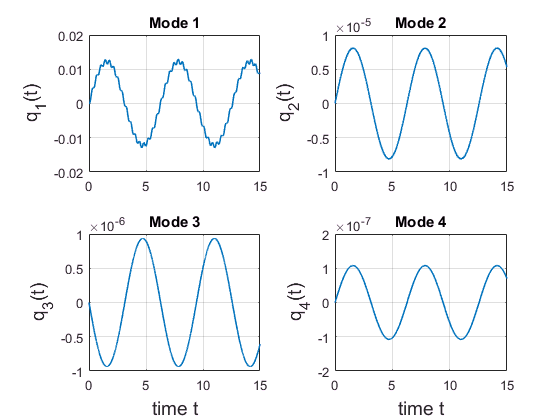

% System dynamics:
karr = -(E*I*D2Phiarr(:,1)./(omeg.^2)+m*L*Phiarr(:,end))/(J*Al*rho);
B = [0;1/J;kron(karr,[0;1])];
A = blkdiag([0 1;0 0],kron(-diag(omeg.^2),[0 0;1 0])+kron(eye(N),[0 1;0 0]));
% Time simulation:
z0 = zeros(2*(N+1),1);
u = @(t)(5e-2*sin(t));
% u = @(t)(4e-2); % constant torque
% u = @(t)(3e-2*torque1(t)); % accelerate + constant torque
% u = @(t)(3e-2*torque2(t)); % accelerate + break
% u = @(t)(5e-2*sin(omeg(1)*t)); % resonance
% z0 = [0 0 kron(exp(-[1:N]),[1 0])]'; % acceleration by IC
% u = @(t)(0);
fdyn = @(t,z)(A*z+B*u(t));
[time,zsol] = ode45(fdyn,time,z0); %ode23s(fdyn,time,z0);
% Test vibration components:
figure;
subplot(2,2,1); plot(time,zsol(:,1+2*1),'LineWidth',1)
grid; ylabel('q_1(t)','FontSize',14); title('Mode 1')
subplot(2,2,2); plot(time,zsol(:,1+2*2),'LineWidth',1)
grid; ylabel('q_2(t)','FontSize',14); title('Mode 2')
subplot(2,2,3); plot(time,zsol(:,1+2*3),'LineWidth',1)
grid; xlabel('time t','FontSize',14); ylabel('q_3(t)','FontSize',14); title('Mode 3')
subplot(2,2,4); plot(time,zsol(:,1+2*4),'LineWidth',1)
grid; xlabel('time t','FontSize',14); ylabel('q_4(t)','FontSize',14); title('Mode 4')

# 3.3 Compound system simulation

Overall deformation:


$$w(x,t)=\overset{\infty}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)\approx\overset{N}{\underset{i=1}{\sum}}\phi_i(x)q_i(t)$$


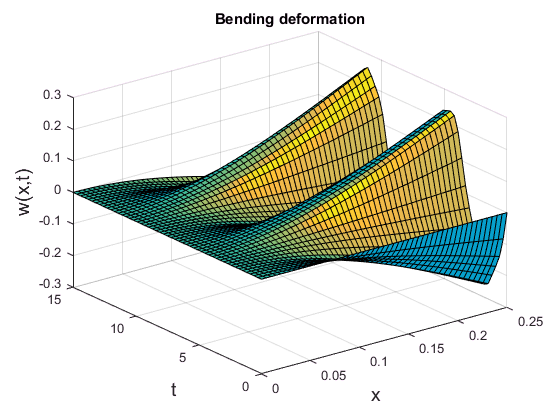

% Deformation solution:
qsol = zsol(:,3:2:end-1)';
time = time';
w = zeros(length(time),length(X));
for j=1:length(time) % build over time
    tmpcol = sum(diag(qsol(:,j))*phiarr);
    w(j,:) = tmpcol;
end
% Select rough grid:
nappr = 50; % grid approximation
lx = length(X); indx = 1:round((lx-1)/nappr):lx;
Xpl = X(indx);
lt = length(time); indt = 1:round((lt-1)/nappr):lt;
Tpl = time(indt)';
% 3D deformation plot:
wpl = w(indt,indx);
figure; surfl(Xpl,Tpl,wpl); %shading flat
xlabel('x','FontSize',14); ylabel('t','FontSize',14); zlabel('w(x,t)','FontSize',14);
title('Bending deformation')

Total flexible arm movement (see figure):


$$(X,Y)=\big[x\cos(\theta(t))-w(x,t)\sin(\theta(t))\,,\,x\sin(\theta(t))+w(x,t)\cos(\theta(t))\big]$$


with the compound rotation angle:


$$\theta(t)=\eta(t)+\overset{\infty}{\underset{i=1}{\sum}}\,\gamma_iq_i(t)\approx \eta(t)+\overset{N}{\underset{i=1}{\sum}}\,\gamma_iq_i(t)$$


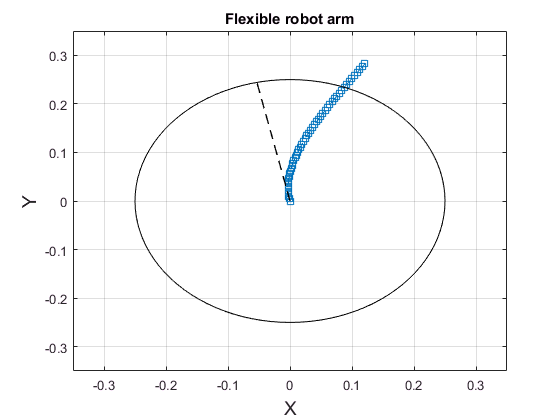

% Rotation angle:
etasol = zsol(:,1)';
thetasol = etasol + gamma'*qsol;
% Cartesian representation:
Xcart = zeros(length(time),length(X)); Ycart = zeros(length(time),length(X));
Xnom = zeros(length(time),length(X)); Ynom = zeros(length(time),length(X));
for j=1:length(time) % build over time    
    Xcart(j,:) = X*cos(thetasol(j)) - w(j,:)*sin(thetasol(j));
    Ycart(j,:) = X*sin(thetasol(j)) + w(j,:)*cos(thetasol(j));
    Xnom(j,:) = X*cos(thetasol(j));
    Ynom(j,:) = X*sin(thetasol(j));
end
% Flexible arm plot:
for k=1:length(Tpl)
    plot(Xcart(indt(k),indx),Ycart(indt(k),indx),'--s'); grid
    hold on; plot(Xnom(indt(k),indx),Ynom(indt(k),indx),'--black','LineWidth',1);
    circle(0,0,L); hold off
    axis([-L L -L L]+[-0.1 0.1 -0.1 0.1])
    xlabel('X','FontSize',14); ylabel('Y','FontSize',14); title('Flexible robot arm')
    %MV(k) = getframe; % movie structure: [figure; movie(MV)]
end

COMMENTS:

- more general assumption: direct influence of modes $q_i$ on rotation angle $\theta$

- after difficult preconsiderations relatively simple model structure obtained

- decoupled mode dynamics (oscillatory blocks in dynamic matrix $A$)

- fast time simulation, even for high model order

- every mode just contains its eigenfrequency and the excitation frequency

- approach most frequently used in literature

- results seem a lot more reasonable than for the constrained approach

$\rightarrow$ selected system structure for simulation and control design with BC *(I.)*

# 4. Model extension

Based on: **[MoranEstikoTanakaHayase1996]** $\text{H}_\infty$* Control of a flexible arm considering motor  dynamics and optimum sensor location *

## Damping & motor model

The arm is rotated by a DC motor and the respective back-electromotive force shall be included into the modelling approach. Consider the input law for the torque:


$$u(t)=\frac{K_t}{R_a}\,\big(v(t)-K_e\dot\theta(t)\big)$$


where $K_t$ the torque constant, $R_a$ the internal resistance and $K_e$ the electromotive constant. Additionally the viscosity on the motor shaft/spindle $D\dot\eta$ and on arm and payload $2\zeta_i\omega_i\dot q_i$ shall be included.

For the unconstrained mode flexible arm model, plugging these extension in holds:


$$J\ddot\eta(t)+\left(\frac{K_tK_e}{R_a}+D\right)\dot\eta(t)+\frac{K_tK_e}{R_a}\overset{\infty}{\underset{i=1}{\sum}}\gamma_iq_i(t)=\frac{K_t}{R_a}\,v(t)$$



$$\ddot q_j(t)+\left(\frac{K_tK_e}{R_a}\overset{\infty}{\underset{i=1}{\sum}}\gamma_i\dot q_i(t)+2\zeta_j\omega_j\,\dot q_j(t)\right)+\omega_j^2q_j=k_j\frac{K_t}{R_a}\,v(t)$$


COMMENTS

- introduces again lots of couplings

- not clear how to select damping factors $\zeta_i$

- literature source seems to contain index errors